# Analysis of Monte Carlo Results

Analysis the simulation results in more detail. In particular, consider any variation caused by the signal-to-noise ratio. 

## Load Monte Carlo simulation results

Load the data from the Monte Carlo simulation. 

% Find base directory
basedir = fileparts(pwd);

% Set data directory
datadir = fullfile(basedir,"data","DataExamplesv2");

% Set model director and file
modeldir = fullfile(basedir,"data","Models");
modelfilename = "ModelCepstral26CubicSvm.mat";
% model variable name is mdlCepstral25CubicSvm
nfeatures = 26;

% Set Monte Carlo directory and file
mcfolder = fullfile(basedir,"data","MonteCarlo");
mcfilename = "mcCepstral26CubicSvmResults.mat";

% Create pool of MATLAB workers
% tic; parpool('local',4); toc

% Load data
load(fullfile(mcfolder,mcfilename))

## Overall statistics

% Overall statistics
summary(tmcoutput)


Variables:

    BlockLength: 100000×1 double

        Values:

            Min         1.024e+05  
            Median      1.024e+05  
            Max         1.024e+05  

    SignalFile: 100000×1 string

    SignalStartIndx: 100000×1 double

        Values:

            Min                   1    
            Median       6.9573e+05    
            Max          8.0253e+06    

    ContaminatedTrue: 100000×1 logical

        Values:

            True           50166       
            False          49834       

    FracBlockContaminated: 100000×1 double

        Values:

            Min                     0        
            Median            0.25258        
            Max               0.99998        

    ContaminationStartIndx: 100000×1 double

        Values:

            Min                    0          
            Median              35.5          
            Max       

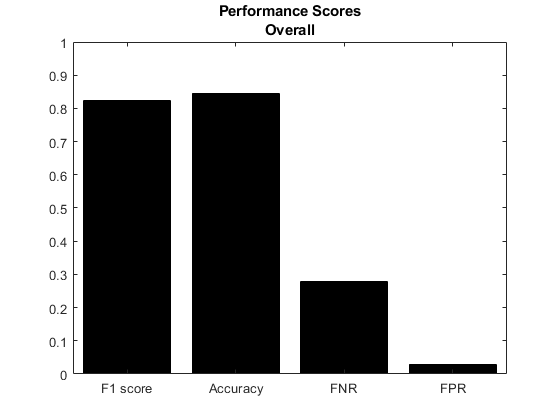

% Overall scores
[acc,fpr,fnr,f1] = scoreModel(tmcoutput.ContaminatedTrue,tmcoutput.ContaminatedPred);
scoresOA.acc = acc;
scoresOA.f1 = f1;
scoresOA.fpr = fpr;
scoresOA.fnr = fnr;
% Plot scores for comparison
c = categorical({'F1 score','Accuracy','FNR','FPR'},{'F1 score','Accuracy','FNR','FPR'});
bar(c,[f1; acc; fnr; fpr],'FaceColor','k');
ylim([0 1])
title({'Performance Scores';'Overall'})

## Contaminated files only

% Contaminated files only
tcontaminated = tmcoutput(tmcoutput.ContaminatedTrue == 1,:);
summary(tcontaminated)


Variables:

    BlockLength: 50166×1 double

        Values:

            Min         1.024e+05  
            Median      1.024e+05  
            Max         1.024e+05  

    SignalFile: 50166×1 string

    SignalStartIndx: 50166×1 double

        Values:

            Min                   6    
            Median       6.9606e+05    
            Max          8.0253e+06    

    ContaminatedTrue: 50166×1 logical

        Values:

            True           50166       
            False              0       

    FracBlockContaminated: 50166×1 double

        Values:

            Min               0.25001        
            Median            0.62615        
            Max               0.99998        

    ContaminationStartIndx: 50166×1 double

        Values:

            Min                    1          
            Median             14454          
            Max             

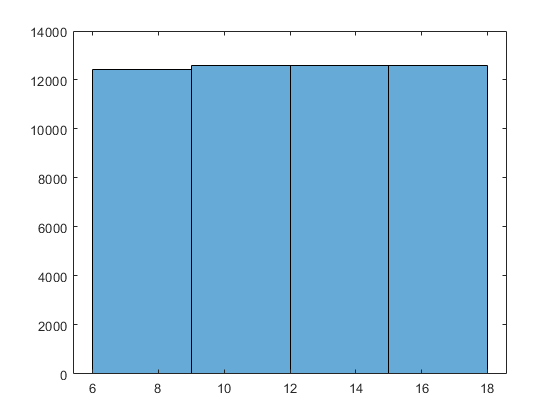

% Signal-to-noise ratio
edges = 6:3:18;
histogram(tcontaminated.SNRdB,edges)

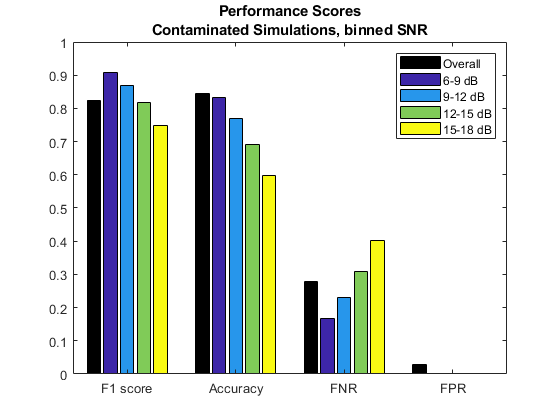

binsSNR = discretize(tcontaminated.SNRdB,edges);

[acc,fpr,fnr,f1] = splitapply(@scoreModel,tcontaminated.ContaminatedTrue,tcontaminated.ContaminatedPred,binsSNR);
% Plot scores for comparison
c = categorical({'F1 score','Accuracy','FNR','FPR'},{'F1 score','Accuracy','FNR','FPR'});
b = bar(c,[[scoresOA.f1 f1']; [scoresOA.acc acc']; [scoresOA.fnr fnr']; [scoresOA.fpr fpr']],'FaceColor','flat');
ylim([0 1])
legend({'Overall','6-9 dB','9-12 dB','12-15 dB','15-18 dB'})
title({'Performance Scores';'Contaminated Simulations, binned SNR'})
b(1).CData = [0 0 0];
for k = 1:length(unique(binsSNR))
    b(k+1).CData = k;
end

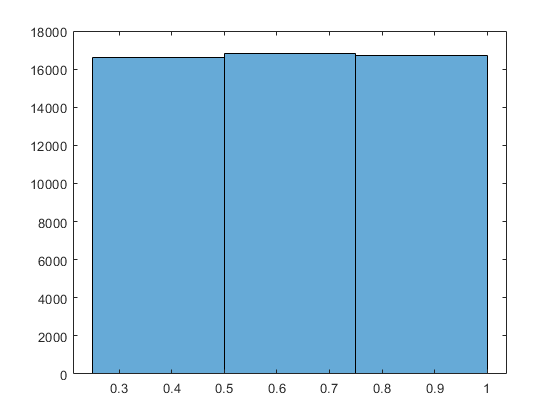

% Fraction of signal block contaminated
edges = 0.25:0.25:1;
histogram(tcontaminated.FracBlockContaminated,edges)

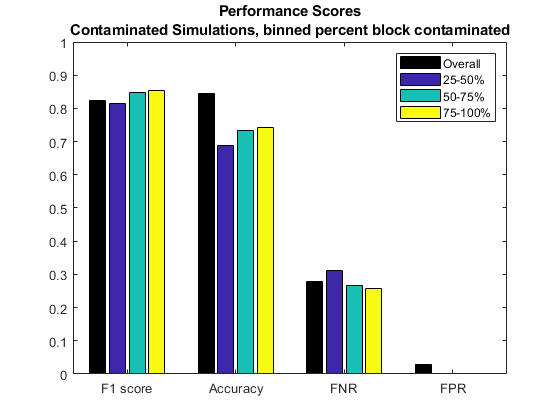

binsfracblock = discretize(tcontaminated.FracBlockContaminated,edges);

[acc,fpr,fnr,f1] = splitapply(@scoreModel,tcontaminated.ContaminatedTrue,tcontaminated.ContaminatedPred,binsfracblock);
% Plot scores for comparison
c = categorical({'F1 score','Accuracy','FNR','FPR'},{'F1 score','Accuracy','FNR','FPR'});
b = bar(c,[[scoresOA.f1 f1']; [scoresOA.acc acc']; [scoresOA.fnr fnr']; [scoresOA.fpr fpr']],'FaceColor','flat');
ylim([0 1])
legend({'Overall','25-50%','50-75%','75-100%'})
title({'Performance Scores';'Contaminated Simulations, binned percent block contaminated'})
b(1).CData = [0 0 0];
for k = 1:length(unique(binsfracblock))
    b(k+1).CData = k;
end

## Analysis of Variance?

Statistical method to estimate how impactiful the changes in SNR and percentage of block contaminated are on the ability of the model to correctly predict the class.

% Create table for analysis
tanova = tmcoutput(:,{'FracBlockContaminated','SNRdB'});
tanova.CorrectPred = tmcoutput.ContaminatedTrue == tmcoutput.ContaminatedPred;

% Check correlation between FracBlockContaminated and SNRdB
% Only valid for contaminated blocks as the non-contaminated blocks have zero for both!
IdxCont = tmcoutput.ContaminatedTrue;
corrcoef(tanova.FracBlockContaminated(IdxCont),tanova.SNRdB(IdxCont))

ans =     1.0000    0.0035
    0.0035    1.0000



% Create logistic regression model
mdl11 = fitglm(tanova(IdxCont,:),'linear','distr','binomial')

mdl11 = Generalized linear regression model:
    logit(CorrectPred) ~ 1 + FracBlockContaminated + SNRdB
    Distribution = Binomial

Estimated Coefficients:
                             Estimate       SE         tStat       pValue  
                             ________    _________    _______    __________

    (Intercept)                2.2464     0.048713     46.116             0
    FracBlockContaminated     0.64382     0.047191     13.643    2.2261e-42
    SNRdB                    -0.13669    0.0030398    -44.966             0


50166 observations, 50163 error degrees of freedom
Dispersion: 1
Chi^2-statistic vs. constant model: 2.31e+03, p-value = 0

mdl22 = fitglm(tanova(IdxCont,:),'quadratic','distr','binomial')

mdl22 = Generalized linear regression model:
    logit(CorrectPred) ~ 1 + FracBlockContaminated*SNRdB + FracBlockContaminated^2 + SNRdB^2
    Distribution = Binomial

Estimated Coefficients:
                                    Estimate         SE         tStat       pValue  
                                   __________    __________    _______    __________

    (Intercept)                        1.4325       0.19357     7.4001    1.3605e-13
    FracBlockContaminated              3.7572       0.34538     10.878    1.4621e-27
    SNRdB                            -0.14402      0.025429    -5.6636    1.4823e-08
    FracBlockContaminated:SNRdB     -0.015714      0.013828    -1.1364       0.25579
    FracBlockContaminated^2           -2.3513       0.24071    -9.7684    1.5